## Error Analysis

## 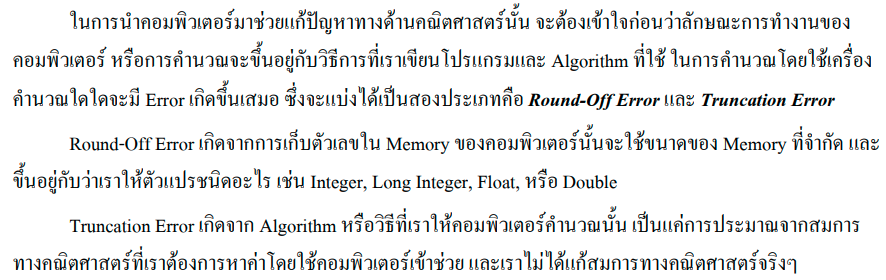

Modeling Error มาจากการตั้งระบบ/สมมุติฐาน  ไม่ครบ

clear
clc

## Error Definitions

- True Error (Absolute Error)

syms trueValue trueError approximationValue
trueError(trueValue,approximationValue) = trueValue - approximationValue

$$trueError(trueValue, approximationValue) = \mathrm{trueValue}-\mathrm{approximationValue}$$

- Relative Error

syms epsilon_t trueValue approximationValue
epsilon_t(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue)*100

$$epsilon\_t(trueValue, approximationValue) = \frac{100\,\left|\mathrm{approximationValue}-\mathrm{trueValue}\right|}{\left|\mathrm{trueValue}\right|}$$

- Approximation Error

syms epsilon_a approximationValue_previous approximationValue_present
epsilon_a(approximationValue_previous,approximationValue_present) = ( ...
    (approximationValue_present - approximationValue_previous)/approximationValue_present)*100

$$epsilon\_a(approximationValue\_previous, approximationValue\_present) = \frac{100\,\left({\mathrm{approximationValue}}_{\mathrm{present}}-{\mathrm{approximationValue}}_{\mathrm{previous}}\right)}{{\mathrm{approximationValue}}_{\mathrm{present}}}$$

## Find Derivative form Finite Divided-Difference  

Taylor Series Expansion (Truncation Errors)

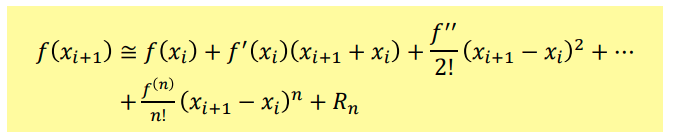

syms x
taylor(exp(x), x)

$$ans = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

taylor(exp(x), x, 'Order', 6)

$$ans = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

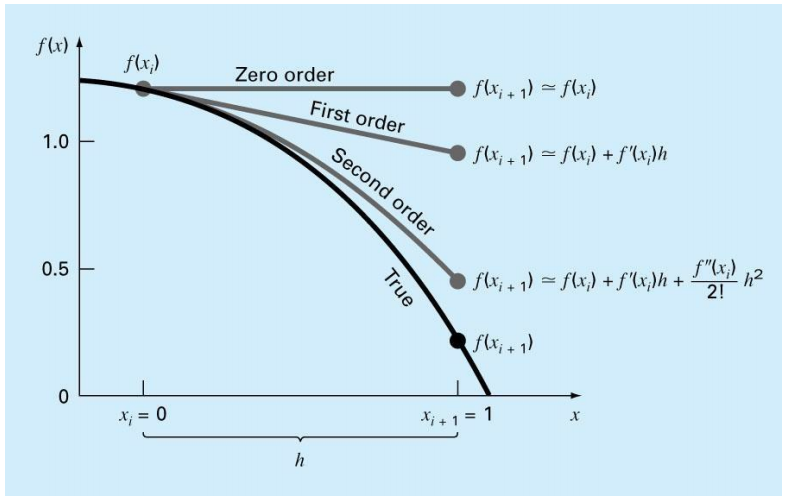

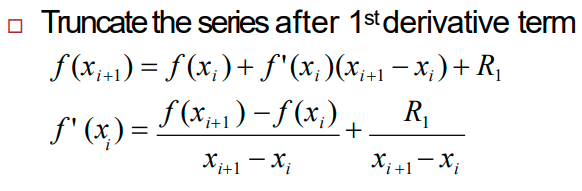

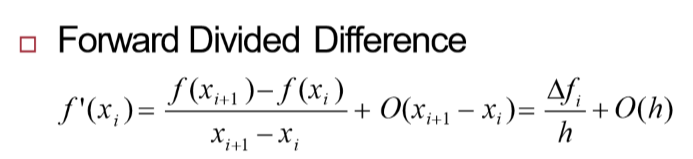

### Example

%Initialization Workspace
clear
clc

%Initial Function
STEP_SIZE = 0.5;
x_i = 0.5;

syms function_x x
function_x(x) = -0.1*(x^4) - 0.15*(x^3) - 0.5*(x^2) - 0.25*x + 1.2

$$function\_x(x) = -\frac{x^{4}}{10}-\frac{3\,x^{3}}{20}-\frac{x^{2}}{2}-\frac{x}{4}+\frac{6}{5}$$

%Algorithm Approximation Value : First Order Taylor Series
x_i_forward = x_i + STEP_SIZE;

trueValue_x_i = function_x(x_i);
trueValue_x_i_forward = function_x(x_i_forward);

approximationValue_order1_x_i = (trueValue_x_i_forward - trueValue_x_i) / (x_i_forward - x_i);

fprintf('Approximation Value : %f \n', approximationValue_order1_x_i)

Approximation Value : -1.450000 


%True Value
trueFunction_order1_x(x) = diff(function_x(x));
trueValue_order1_x_i = trueFunction_order1_x(x_i);

fprintf('True Value: %f \n', trueValue_order1_x_i)

True Value: -0.912500 


%Approximation Error
syms epsilon_t trueValue approximationValue
epsilon_t(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue)*100;

fprintf('Approximation Error: %f%%\n', epsilon_t(trueValue_order1_x_i, approximationValue_order1_x_i))

Approximation Error: -58.904110%


### Backward Difference


$$f^{\prime } \left(x_i \right)\cong \;\frac{f\left(x_i \right)-f\left(x_{i-1} \right)}{h}$$


%Initialization Workspace
clear
clc

%Initial Function
STEP_SIZE = 0.5;
x_i = 0.5;

syms function_x x
function_x(x) = -0.1*(x^4) - 0.15*(x^3) - 0.5*(x^2) - 0.25*x + 1.2

$$function\_x(x) = -\frac{x^{4}}{10}-\frac{3\,x^{3}}{20}-\frac{x^{2}}{2}-\frac{x}{4}+\frac{6}{5}$$

%Algorithm Approximation Value : First Order Taylor Series
x_i_backward = x_i - STEP_SIZE;

trueValue_x_i = function_x(x_i);
trueValue_x_i_backward = function_x(x_i_backward);

approximationValue_order1_x_i = (trueValue_x_i - trueValue_x_i_backward) / STEP_SIZE;

fprintf('Approximation Value : %f \n', approximationValue_order1_x_i)

Approximation Value : -0.550000 


%True Value
trueFunction_order1_x(x) = diff(function_x(x));
trueValue_order1_x_i = trueFunction_order1_x(x_i);

fprintf('True Value: %f \n', trueValue_order1_x_i)

True Value: -0.912500 


%Approximation Error
syms epsilon_t trueValue approximationValue
epsilon_t(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue)*100;

fprintf('Approximation Error: %f%%\n', epsilon_t(trueValue_order1_x_i, approximationValue_order1_x_i))

Approximation Error: 39.726027%
